exp1 = readtable('lab3-exp1.csv');
exp1.current_collector = abs(exp1.Var3) - abs(exp1.Var2);

exp1 = exp1(exp1.Var1 < 0.775, :);
exp1 = exp1(exp1.Var1 > 0.5, :);

v_exp1 = flipud(exp1.Var1);
i_c_exp1 = flipud(exp1.current_collector);
i_b_exp1 = flipud(exp1.Var2);

% Incremental base resistance calculation
r_b_exp1 = diff(v_exp1) ./ diff(i_b_exp1);
r_b_exp1 = r_b_exp1(1:end-2);
% Log-log plot of r_b versus I_b
loglog(i_b_exp1(2:end-2), r_b_exp1, 'bo', 'MarkerSize', 4);
xlabel('Base Current (A)');
ylabel('Incremental Base Resistance (Ohms)');
title('Incremental Base Resistance vs Base Current');

fit_r_b = polyfit(log(i_b_exp1(2:end-2)), log(r_b_exp1), 1);
r_b_fit = exp(polyval(fit_r_b, log(i_b_exp1(2:end))));

% Plotting the theoretical fit for incremental base resistance
hold on;
loglog(i_b_exp1(2:end), r_b_fit, 'r--');
legend('Measured Data', 'Theoretical Fit');

fprintf('Incremental Base Resistance Fit: y = %.4f * x + %.4f\n', fit_r_b(1), fit_r_b(2));

Incremental Base Resistance Fit: y = -0.9655 * x + -3.0799


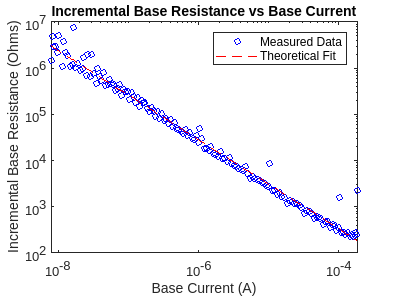


% Extract incremental transconductance gain (g_m)
% g_m_exp1 = diff(i_c_exp1) ./ diff(v_exp1);
% g_m_exp1 = g_m_exp1(1:end-2)
% % Log-log plot of g_m versus I_c
% figure;
% loglog(i_c_exp1(2:end-2), g_m_exp1, 'bo','MarkerSize', 4); 
% xlabel('Collector Current (A)');
% ylabel('Incremental Transconductance Gain (S)');
% title('Incremental Transconductance Gain vs Collector Current');
% 
% fit_g_m = polyfit(log(i_c_exp1(2:end-2)), log(g_m_exp1), 1);
% g_m_fit = exp(polyval(fit_g_m, log(i_c_exp1(2:end))));
% % Plotting the theoretical fit for incremental transconductance gain
% hold on;
% loglog(i_c_exp1(2:end), g_m_fit, 'r--');
% legend('Measured Data', 'Theoretical Fit');
% 
% fprintf('Incremental Transconductance Gain Fit: y = %.4f * x + %.4f\n', fit_g_m(1), fit_g_m(2));
% hold off;
print("-depsc","figures/experiment_1-part21.eps")